# Control How MATLAB Imports Your Data

Import your data into MATLAB® using an importing function, such as `readtable`. You can let MATLAB determine how to import your data, or you can specify parameters to control how MATLAB imports your data. 

Importing functions detect how best to import the contents of your input file by looking at the format of your data based on delimiters, number of header lines, number of variables, types of variables, and metadata. The accuracy of format detection increases with the size of your data set as patterns are more easily recognizable with more data. Text files benefit the most from this analysis because they often have the least structure. 

There are several ways to control how MATLAB imports your data:

- The simplest option is to specify name-value arguments with the importing function. For example, you can specify the `MissingRule` name-value argument to specify how to address gaps in your data. The Import Tool also provides this degree of control, for more information see [docid:matlab_ref#busazkl-1](docid:matlab_ref#busazkl-1).

- Alternatively, you can specify an import options object with the importing function. This option is useful if you want to import multiple files with similar formats, customize at the variable level, or avoid the automatic format detection.

The examples in this topic use `readtable` to import data as tables. For more information about importing data into other formats, such as matrices or cell arrays, see [docid:import_export#f5-35378](docid:import_export#f5-35378) and [docid:import_export#bs5bkj_](docid:import_export#bs5bkj_). 

## Import Data from File into MATLAB

You can import data from a file using an importing function, such as `readtable`. For example, the sample file `outages_flawed.csv` contains column-oriented data:

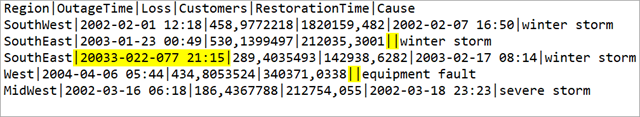

In this sample file, the second and fourth rows of data contain gaps in data, while the third row of data contains a date value that cannot be converted during import. Due to the small size of this data set, only six rows total, any anomaly significantly impacts format detection.

Create a table from `outages_flawed.csv` using the importing function `readtable`. The importing function recognizes the gaps in data as well as the date value that cannot be converted and performs the default action of filling with appropriate missing values.

T = readtable("outages_flawed.csv")

## Control How MATLAB Detects and Imports Your Data

To control how the importing function analyzes your file, you can use name-value arguments. These arguments give you increased control over your import with table-level customization. See the documentation for importing functions for a list of their name-value arguments. This degree of control is appropriate for the majority of workflows.

For example, customize the import of the sample file at the table level by using name-value arguments:

- Set the delimiter to `"|"`.

- Set the decimal separator to `","`.

- Omit rows with data that causes import errors.

- Omit rows with missing data. 

T = readtable("outages_flawed.csv",Delimiter="|",DecimalSeparator=",", ...
    ImportErrorRule="omitrow",MissingRule="omitvar")

## Import Data from Multiple Files and Control Individual Variables

If you have multiple files to import and your files have a similar format, you can reuse the same import configuration for all your files by creating an import options object. You can set up the import options object based on the format of one of the files by using the [docid:matlab_ref#bvcithw](docid:matlab_ref#bvcithw) function and then use that object to specify how to import all your files.

Passing name-value arguments to `detectImportOptions` customizes the import options object at the table level by helping the function detect the format of your data. You can further customize the import options object at the variable level by using the `getvaropts`, `setvartype`, and `setvaropts` functions.

For example, create an import options object with table-level customizations:

- Set the delimiter to `"|"`.

- Set the decimal separator to `","`.

- Omit rows with data that cause import errors.

- Omit rows with missing data. 

opts = detectImportOptions("outages_flawed.csv",Delimiter="|", ...
    DecimalSeparator=",",ImportErrorRule="omitrow",MissingRule="omitrow");

Now fine-tune the import options object with variable-level customizations by using the `getvaropts`, `setvartype`, and `setvaropts` functions.

View the current options for the variables named `Region`, `OutageTime`, and `Loss`. 

getvaropts(opts,["Region","OutageTime","Loss"])

Specify variable-level customizations:

- For the `Region`, `OutageTime`, and `Loss` variables, change their data types to `string`, `datetime`, and `single`, respectively. 

- For the `Cause` variable, trim leading white space from the text. 

- For the `Customers` variable, treat fields containing `0` or `NA` as missing.

opts = setvartype(opts,["Region","OutageTime","Loss"], ...
    ["string","datetime","single"]);
opts = setvaropts(opts,"Cause",WhitespaceRule="trimleading");
opts = setvaropts(opts,"Customers",TreatAsMissing=["0","NA"]);

Import `outages_flawed.csv` and the similarly formatted file `outages_flawed2.csv` with your custom options. 

T = readtable("outages_flawed.csv",opts);
T2 = readtable("outages_flawed2.csv",opts);

## Import Data from Multiple Files with No Format Detection

Instead of using an input file to create an import options object, you can create the import options object without an input file. Based on your input file type, choose a function to create a specific type of import options object: `delimitedTextImportOptions`, `fixedWidthImportOptions`, `xmlImportOptions`, `htmlImportOptions`, or `wordDocumentImportOptions`. You can customize the import options object at the table level using name-value arguments during creation or by adjusting its properties after creation. For variable-level customizations, use the `getvaropts`, `setvartype`, and `setvaropts` functions.

For example, import the two sample files which have a similar format and structure. Create a `delimitedTextImportOptions` object for data with six variables, set the delimiter to `"|"`, and omit rows that error during import.

opts = delimitedTextImportOptions(NumVariables=6, ...
    Delimiter="|",ImportErrorRule="omitrow");

Continue to customize your import options object at the table level by adjusting its properties:

- Omit rows with missing data. 

- Specify that the data lines start on line 2. 

- Specify that the variable names are on line 1.

- Preserve any variable names that include spaces and non-ASCII characters.

opts.MissingRule = "omitrow";
opts.DataLines = 2;
opts.VariableNamesLine = 1;
opts.VariableNamingRule = "preserve";

Further customize your import options at the variable level using the `getvaropts`, `setvartype`, and `setvaropts` functions: 

- Set the data types of the six variables.

- Set the decimal separator to `","` for the third and fourth variables.

opts = setvartype(opts,1:6, ...
    ["string" "datetime" "single" "single" "datetime" "categorical"]);
opts = setvaropts(opts,3:4,DecimalSeparator=",");

Import `outages_flawed.csv` and the similarly formatted file `outages_flawed2.csv` with your custom options.

T = readtable("outages_flawed.csv",opts);
T2 = readtable("outages_flawed2.csv",opts);

*Copyright 2012 The MathWorks, Inc.*